# Plots for report

clear all;
fig_folder = 'D:\Storage\SchoolWork\BU\ME701_Spring2020\ME701_project\figures';

## Search for We and Wu to give optimal setteling time

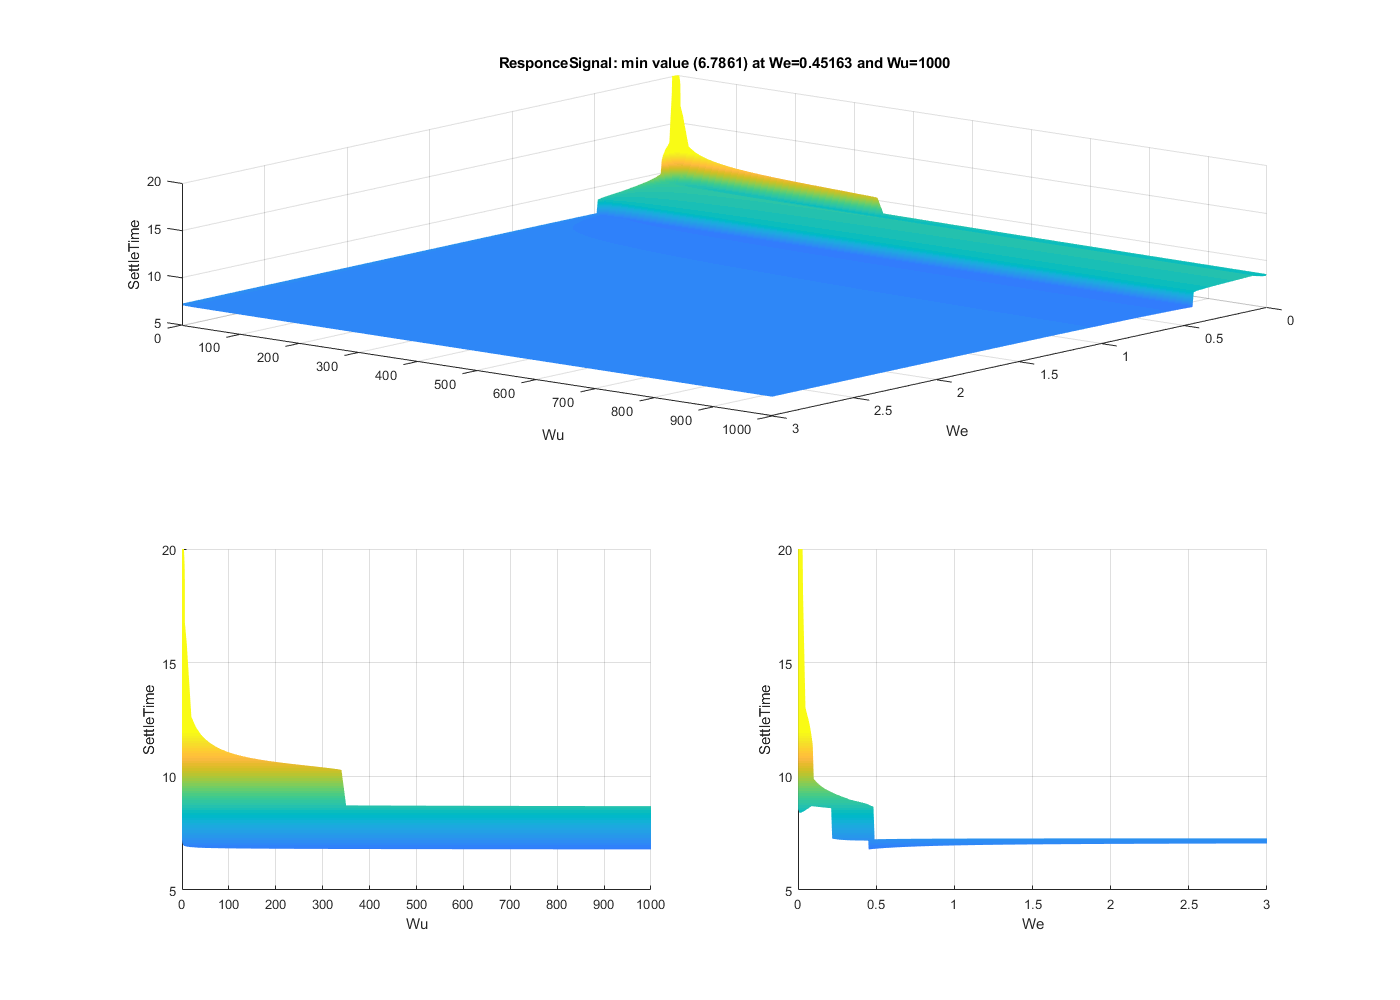

We_Wu_grid = load('dataLogging_We_Wu_grid.mat');
% score(plant_number,We,Wu)
fid(1)=plot_cutoff_search(We_Wu_grid.score_l_h(1,:,:),...
    'x_array',We_Wu_grid.We_array,'x_label','We',...
    'y_array',We_Wu_grid.Wu_array,'y_label','Wu',...
    'z_label','SettleTime');

## Plot Step Responces

### load data

plants = load('plants.mat');
controllers = load('Controllers.mat');

### With Perfect Plant

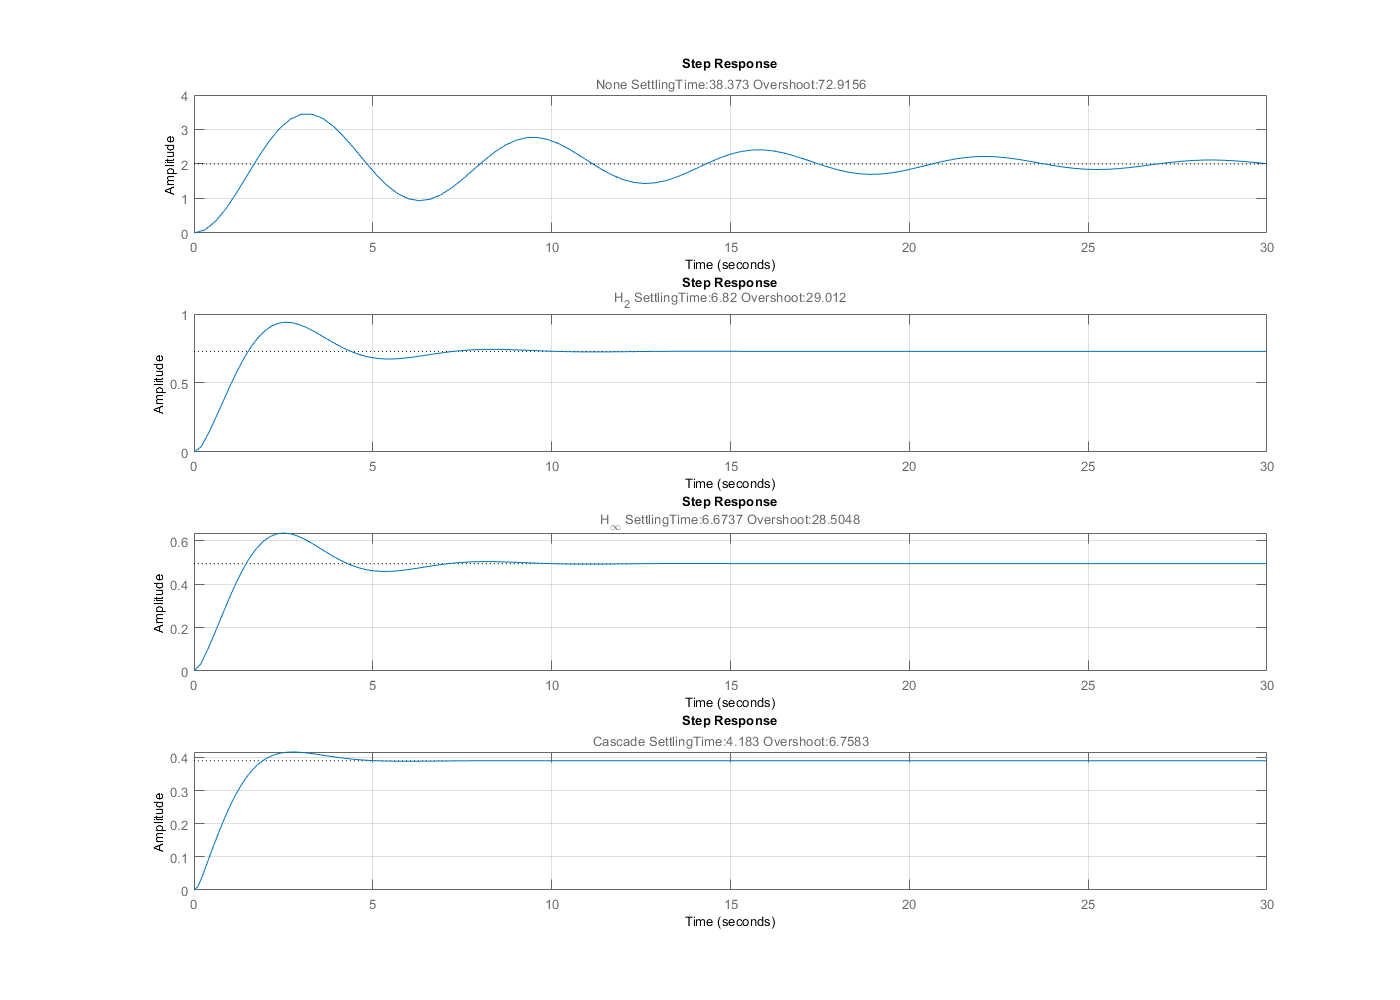

fid(2)=plot_step_responce(controllers,plants,...
    'plant',{'plant_aug','plant_aug','plant_aug','plant_CL_LQR'},...
    'controller',{'controller_none','controller_H2','controller_Hinf','controller_cascade'},...
    'feedback',[1,1,1,1],...
    'title',{'None','H_2','H_\infty','Cascade'},...
    'FigureTitle','StepResponcePerfect_Robust');

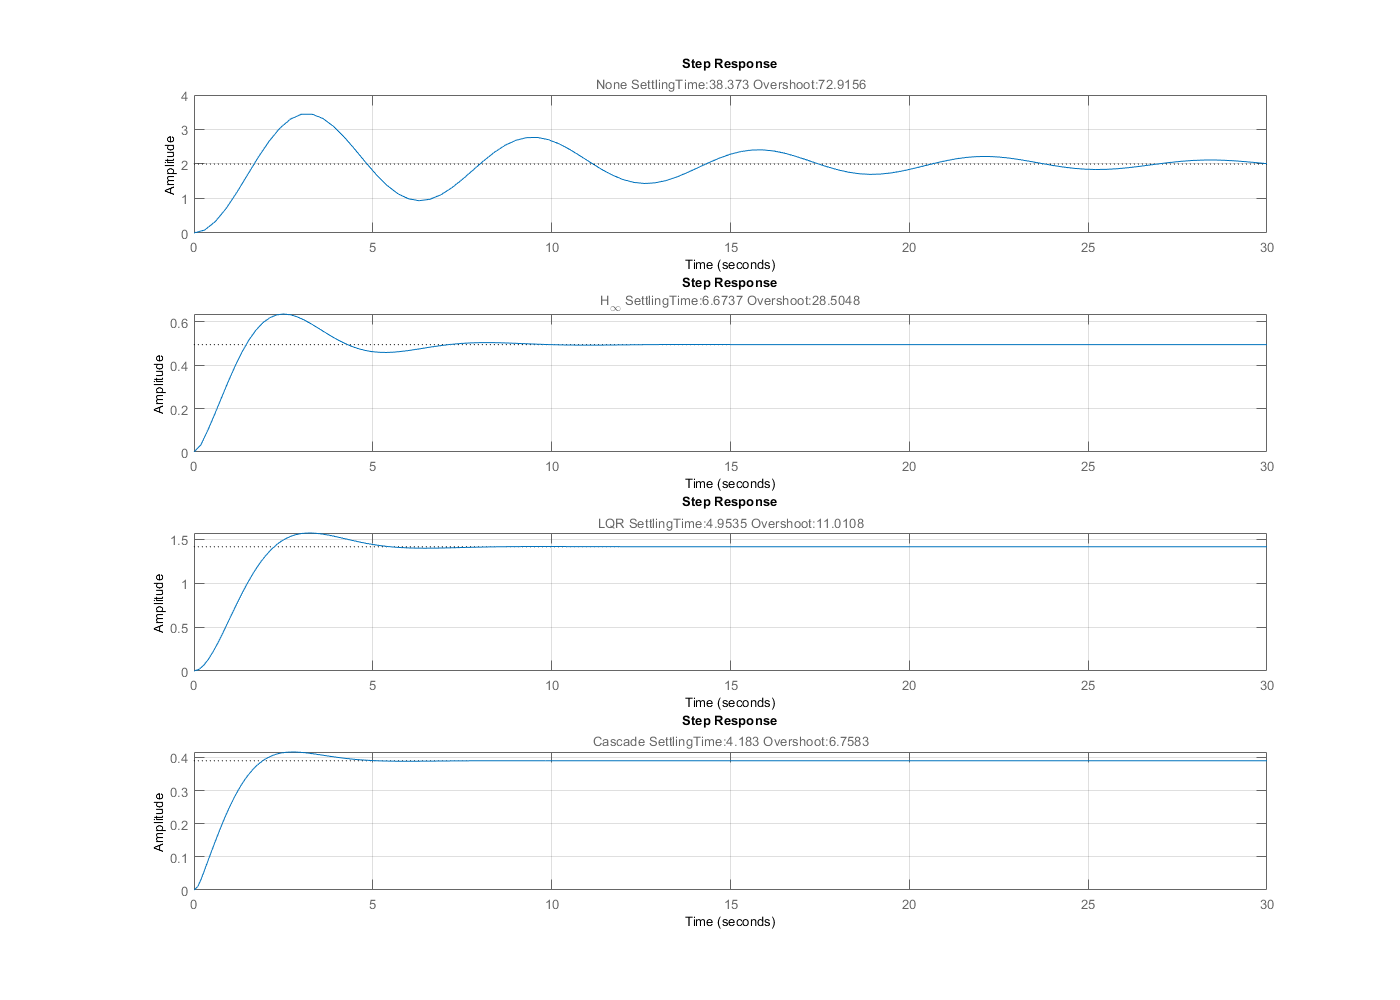


fid(3)=plot_step_responce(controllers,plants,...
    'plant',{'plant_aug','plant_aug','plant_aug','plant_CL_LQR'},...
    'controller',{'controller_none','controller_Hinf','controller_LQR','controller_cascade'},...
    'feedback',[-1,1,-1,1],...
    'title',{'None','H_\infty','LQR','Cascade'},...
    'FigureTitle','StepResponcePerfect_Paper');

### With Plant Errors

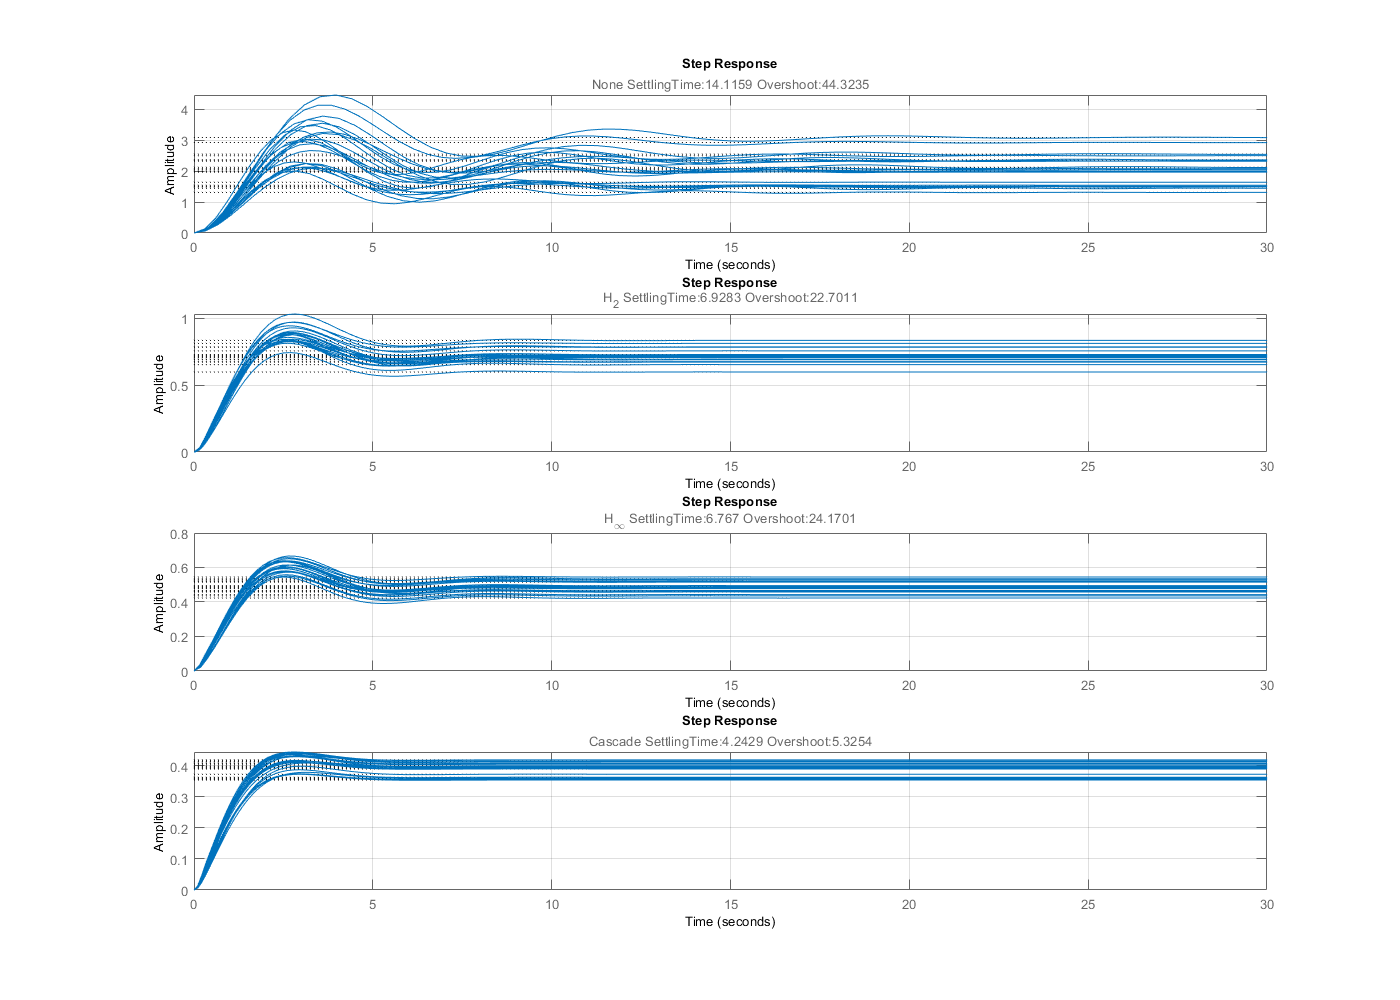

fid(3)=plot_step_responce(controllers,plants,...
    'plant',{'plant_aug_u','plant_aug_u','plant_aug_u','plant_CL_LQR_u'},...
    'controller',{'controller_none','controller_H2','controller_Hinf','controller_cascade'},...
    'feedback',[1,1,1,1],...
    'title',{'None','H_2','H_\infty','Cascade'},...
    'FigureTitle','StepResponceNoise_Robust');

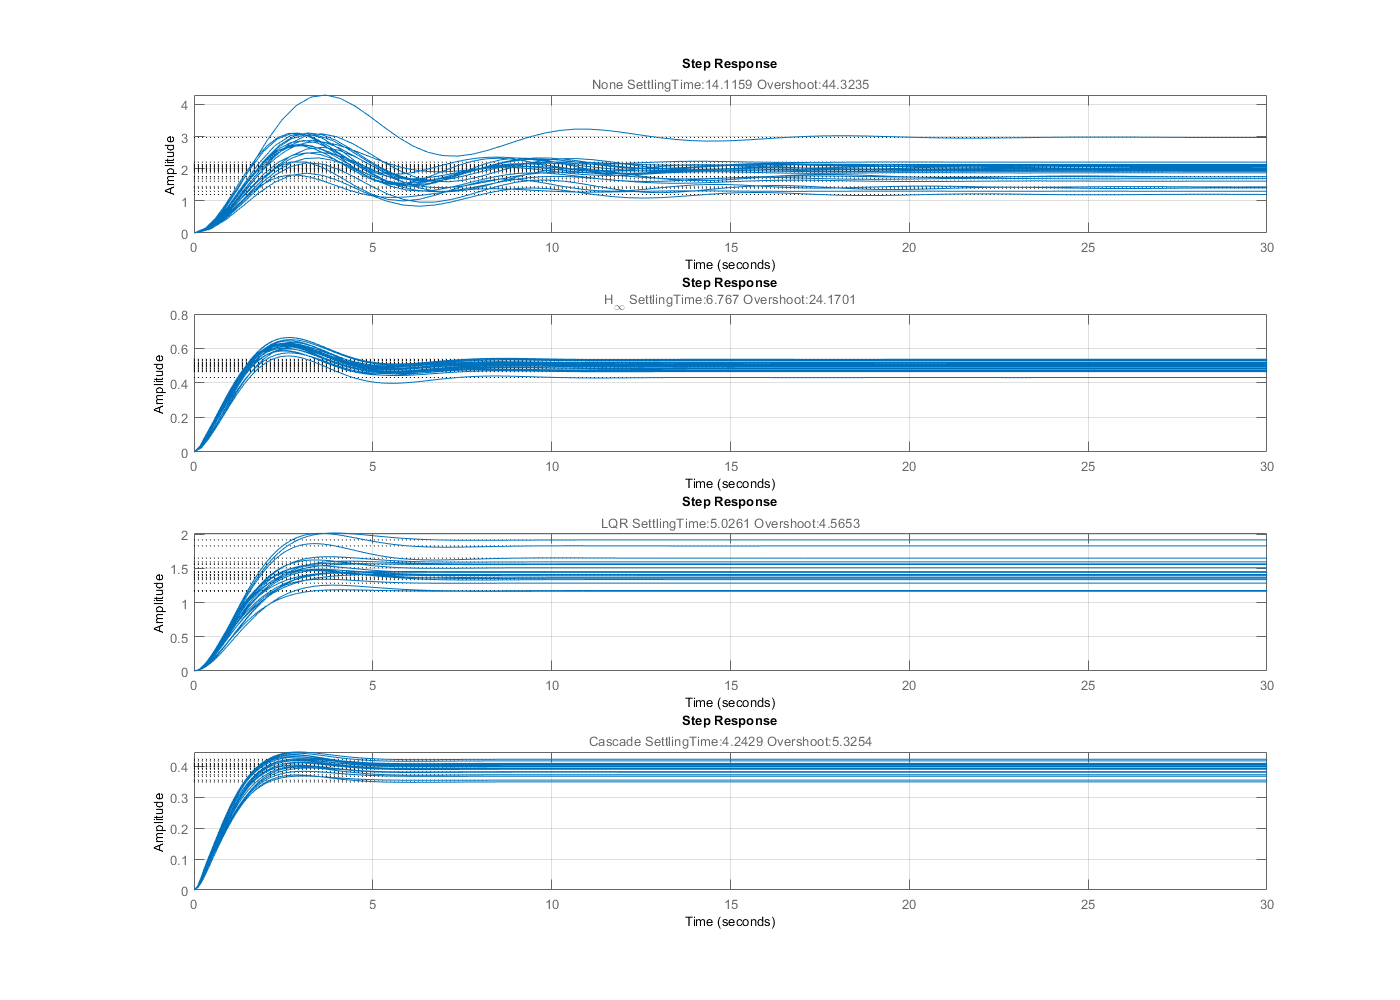


fid(4)=plot_step_responce(controllers,plants,...
    'plant',{'plant_aug_u','plant_aug_u','plant_aug_u','plant_CL_LQR_u'},...
    'controller',{'controller_none','controller_Hinf','controller_LQR','controller_cascade'},...
    'feedback',[-1,1,-1,1],...
    'title',{'None','H_\infty','LQR','Cascade'},...
    'FigureTitle','StepResponceNoise_Paper');

## Plot from simulink results

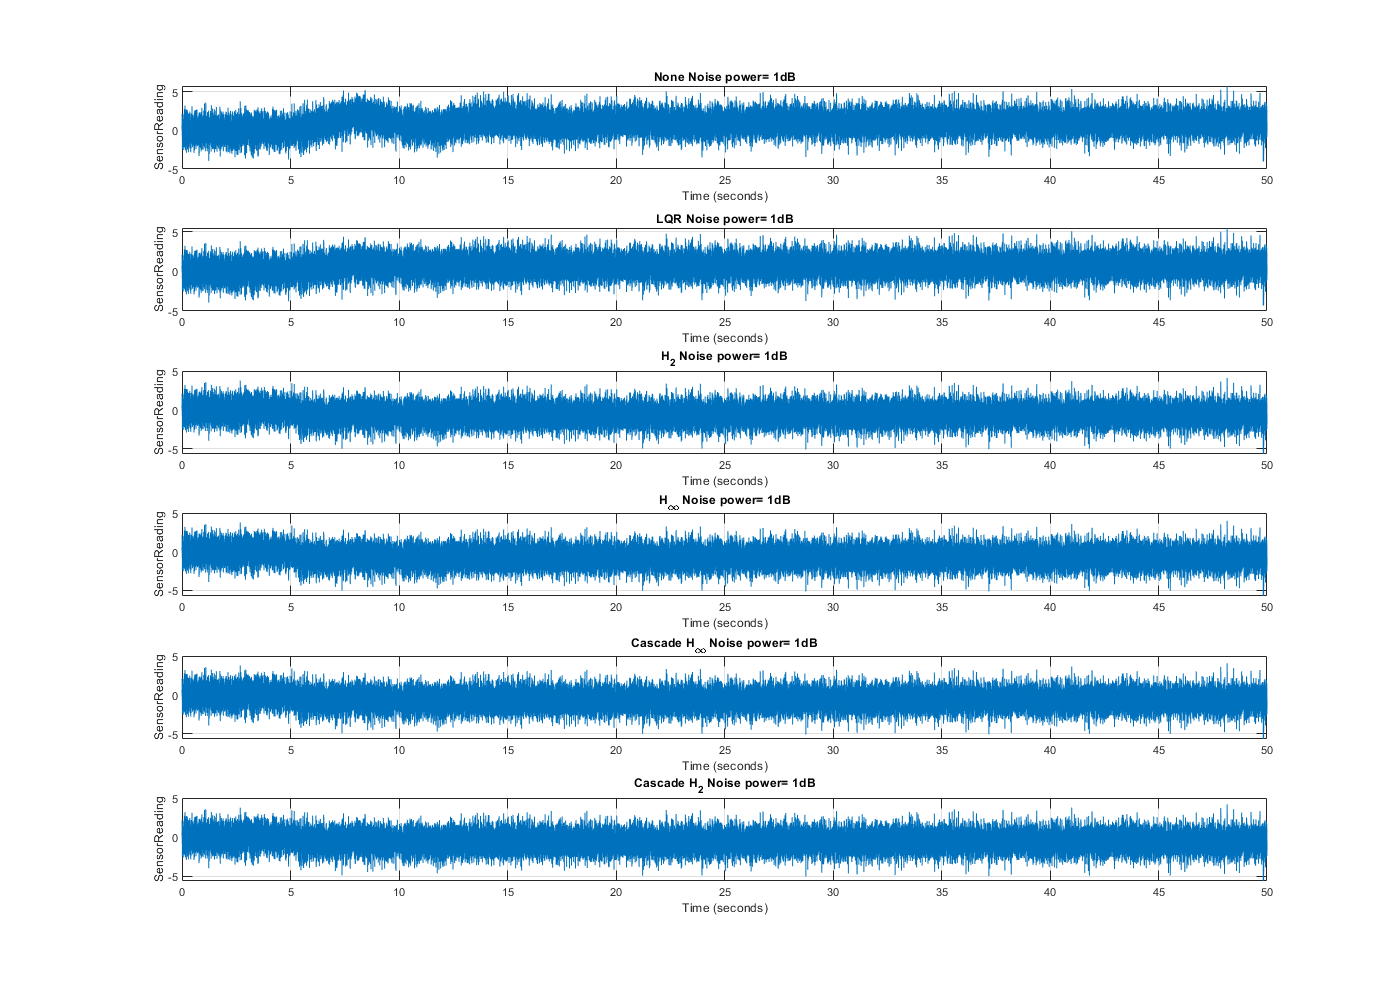

load('sim_results.mat');
keys = {'None','LQR','H2','Hinf','Cascade_Hinf_LQR','H2_LQR'};
titles = {'None','LQR','H_2','H_\infty','Cascade H_\infty','Cascade H_2'};

fid(5)=plot_map(results.Use_Noise,'keys',keys,'title',strcat(titles,' Noise power= 1dB'),'FigureTitle','SimulinkNoiseResponce');

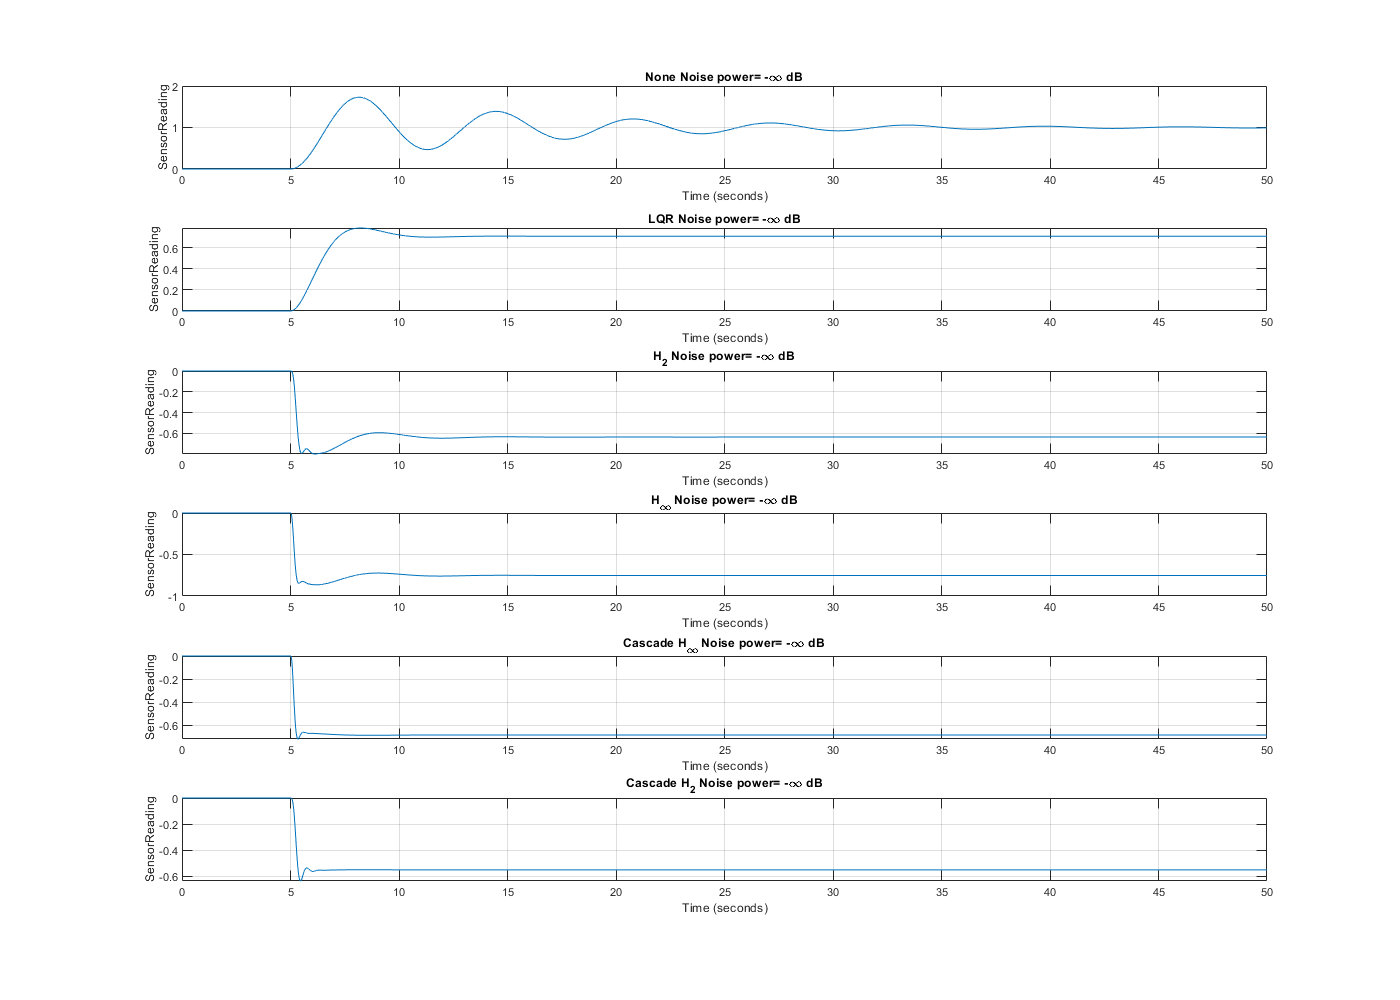

fid(6)=plot_map(results.Dont_Use_Noise,'keys',keys,'title',strcat(titles,' Noise power= -\infty dB'),'FigureTitle','SimulinkTrueResponce');

## Print Results

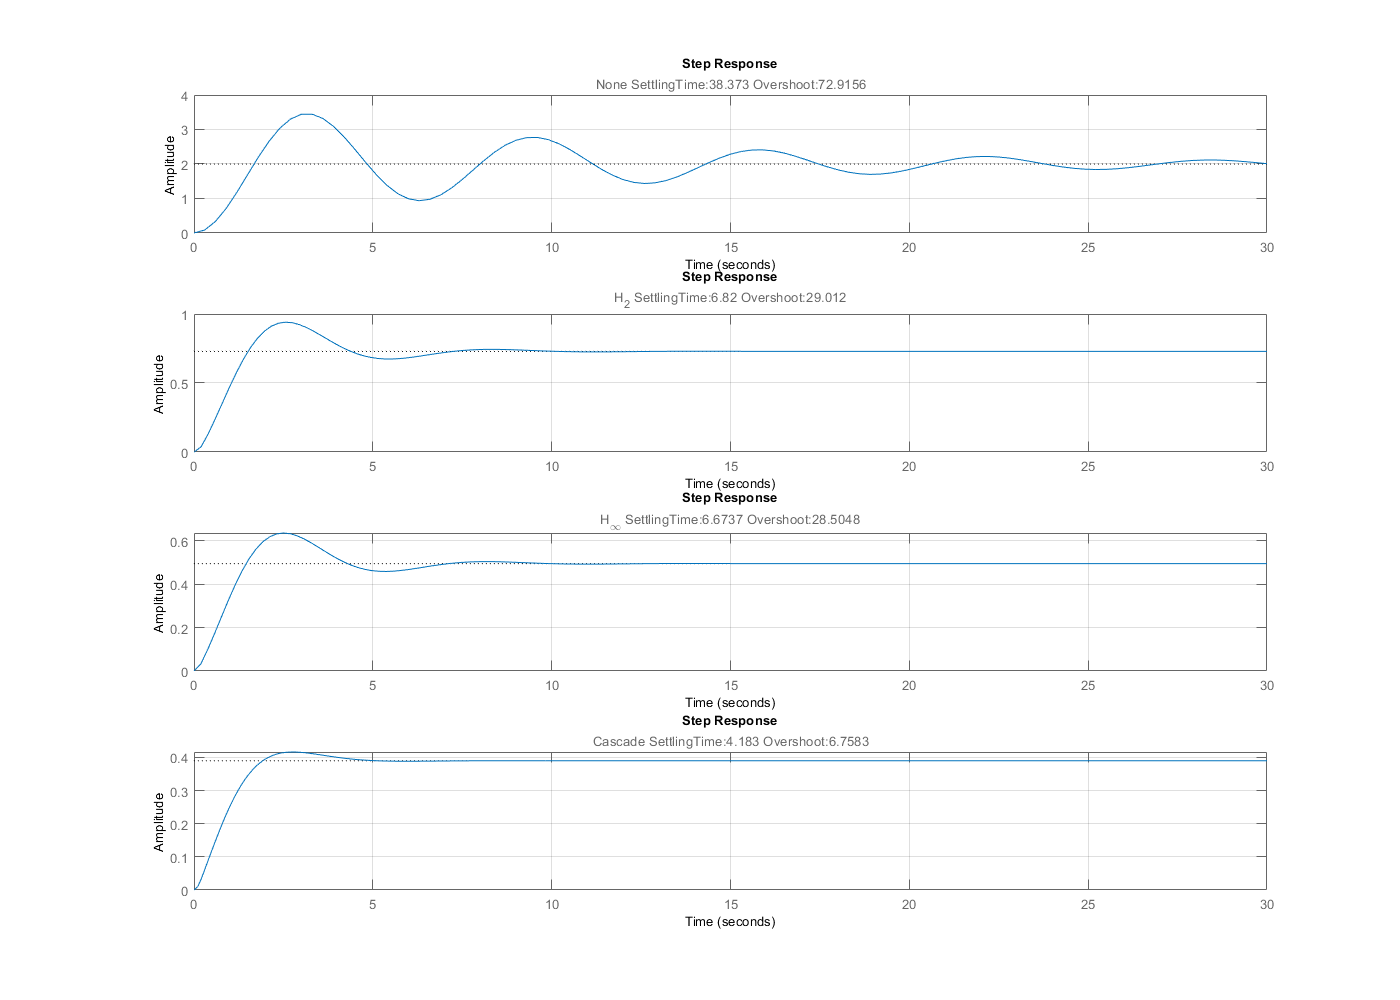

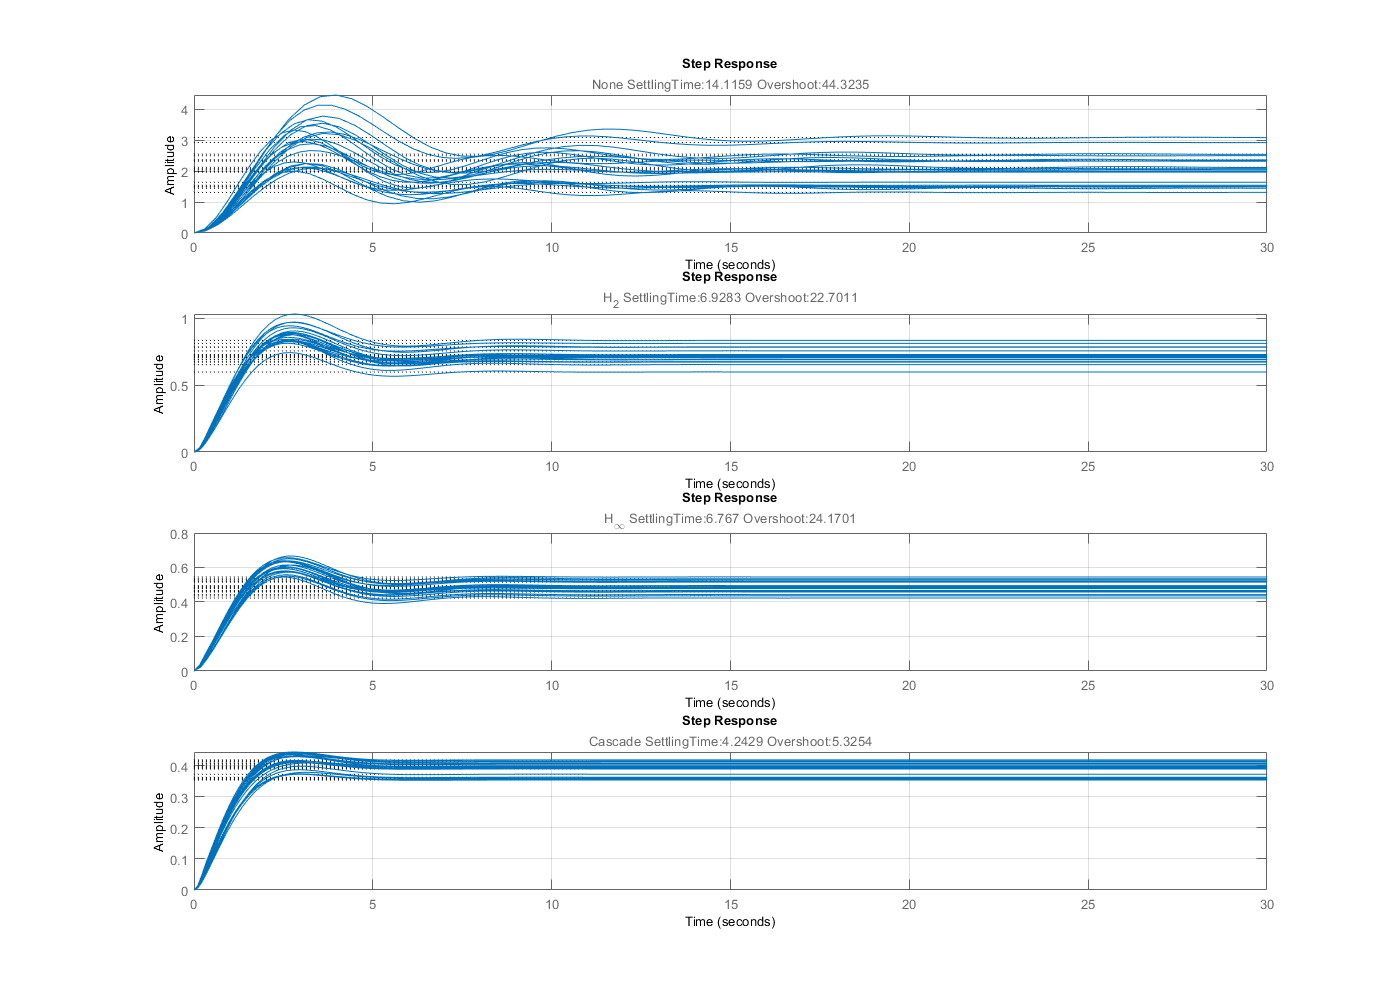

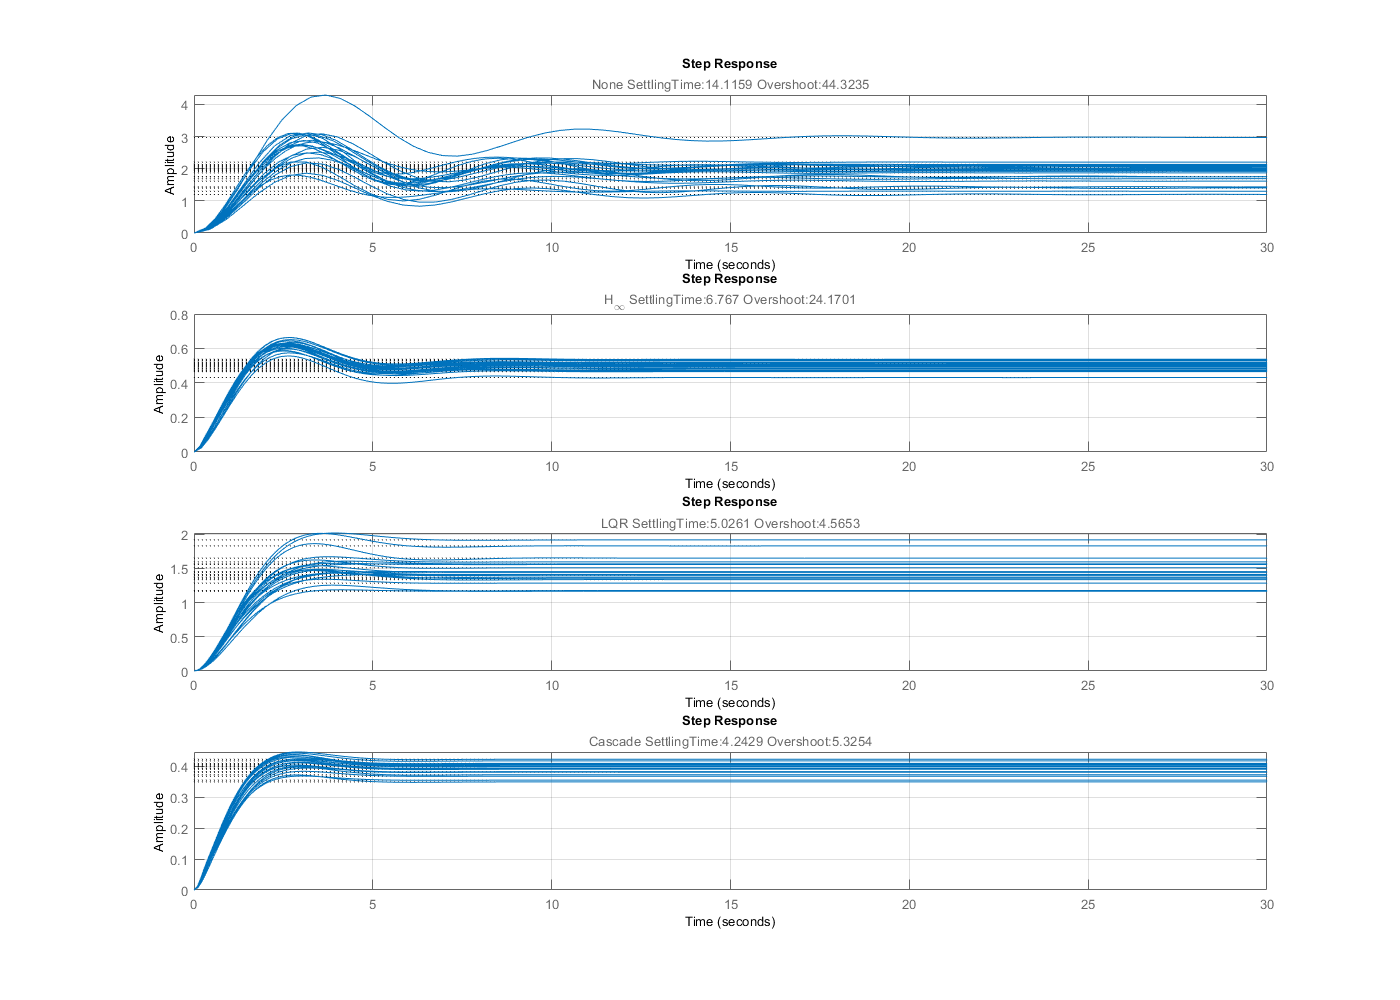

for itr = 1:numel(fid)
    print(fid(itr),[fig_folder,filesep,fid(itr).Name],'-dpdf');
end